# Validate the GLM filters using log likelihood value for the unseen test dataset (loads the outputs of macro.m)

#### Add project source code to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

#### Load GLM fit results

save_path = 'Z:\LabMembers\Jong\model_output_ts_separable\';
mat_files = dir(save_path);
idx = 7; %choose file with index here
disp(mat_files(idx).name);

190510A_clu20_Amsn5x4w000.mat


load(fullfile(save_path, mat_files(idx).name));

#### Plot Receptive Fields (fitted weights of the glm)

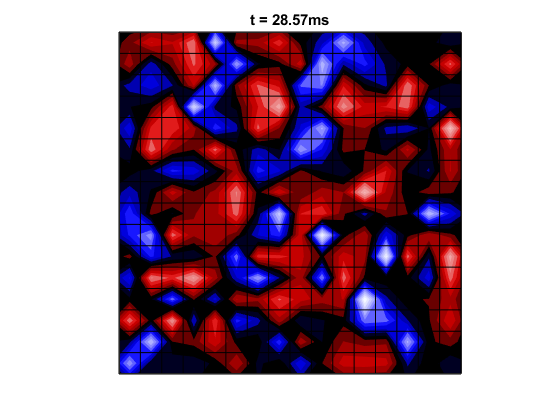

temporal_rf = weight_final(1:25);
glm_sta = reshape(weight_final(26:end), [16,16]);
plot_sta(glm_sta, 1, 1/35);

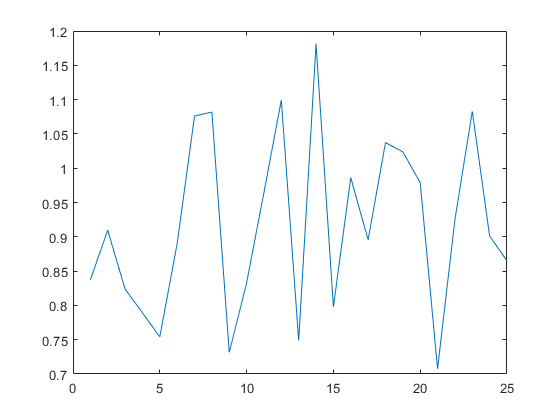

figure;
plot(temporal_rf);

#### Compute Log Likelihood of the Fitted Weights with the test data

neg_logli = neg_log_likli_poisson(test_var, test_lab, weight_final, 1/35, 25, 16);

Neg Log Likelihood: 1958.932
gradient norm length: 218.888


avg_logli = -neg_logli/length(test_lab);

exp(avg_logli)

ans = 0.3447